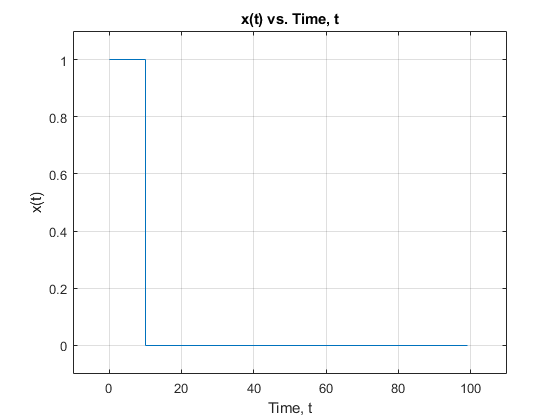

N = 100; PulseWidth = 10;
t = 0:1:(N-1);
x = [ones(1,PulseWidth), zeros(1,N-PulseWidth)];
stairs(t,x); grid on; axis([-10,110,-0.1,1.1]);
title('x(t) vs. Time, t'); xlabel('Time, t'); ylabel('x(t)');

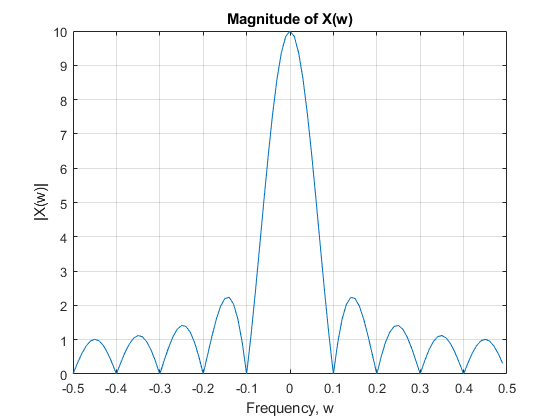


Xf = fft(x);
f = [-(N/2):1:(N/2)-1]*(1/N);

plot(f,fftshift(abs(Xf))); grid on;
title('Magnitude of X(w)'); xlabel('Frequency, w'); ylabel('|X(w)|');

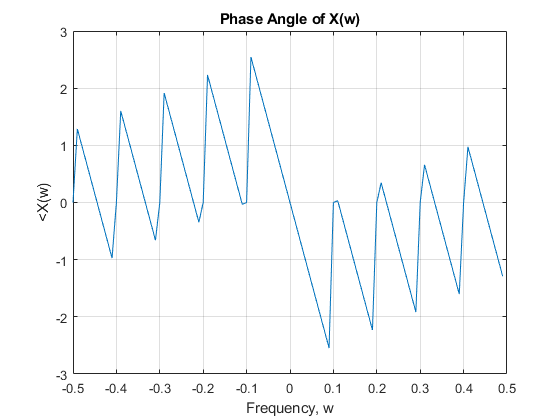

plot(f,fftshift(angle(Xf))); grid on;
title('Phase Angle of X(w)'); xlabel('Frequency, w'); ylabel('<X(w)');


xhat = ifft(Xf);

A.1:Plot of the convolution of x(t) with itself

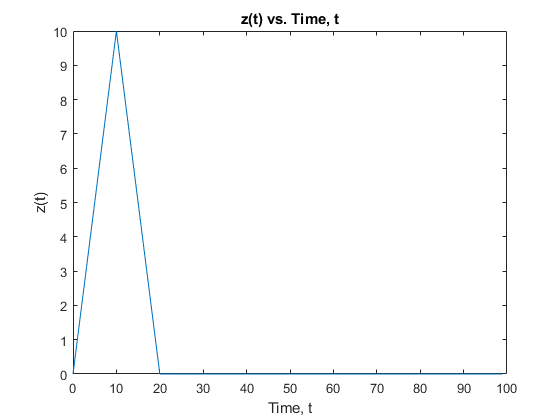

u = @(t) 1.0*(t>=0);
z = @(t) t.*(u(t)-u(t-10)) + (20-t).*(u(t-10)-u(t-20));
plot(t, z(t));
title('z(t) vs. Time, t'); xlabel('Time, t'); ylabel('z(t)');

A.2: Calculation of Z(w) as X(w) squared

Z = fft(x).^2;

A.3: Plotting the Magnitude and Phase Spectra of z(t)

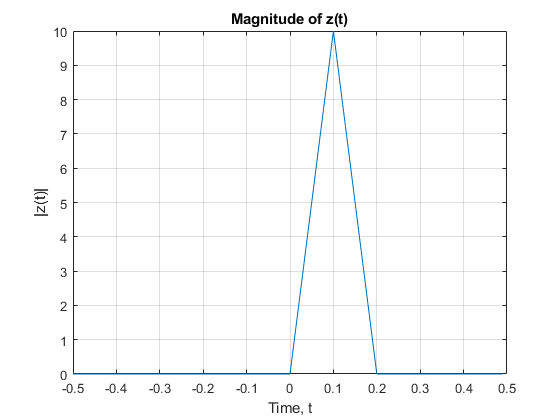

plot(f,fftshift(abs(z(t)))); grid on;
title('Magnitude of z(t)'); xlabel('Time, t'); ylabel('|z(t)|');

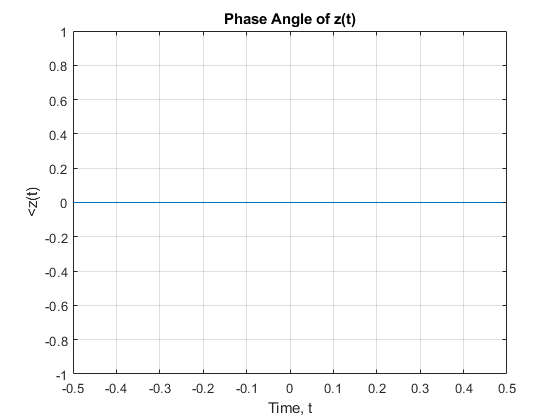

plot(f,fftshift(angle(z(t)))); grid on;
title('Phase Angle of z(t)'); xlabel('Time, t'); ylabel('<z(t)');

A.4: Computing z(t) using MATLAB and plotting both the Magnitude and Phase Spectra of Z(w) and the plot of z(t)

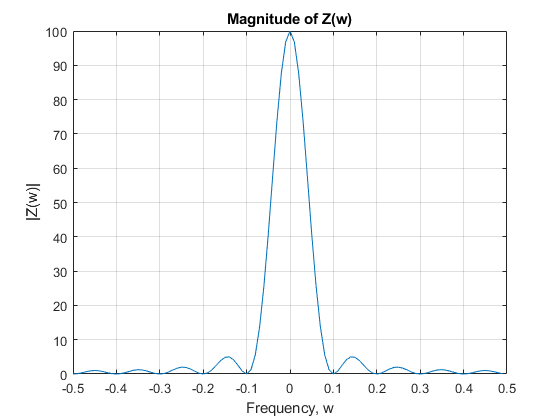

Zw = Xf.^2;
zt = ifft(Zw);

plot(f,fftshift(abs(Zw))); grid on;
title('Magnitude of Z(w)'); xlabel('Frequency, w'); ylabel('|Z(w)|');

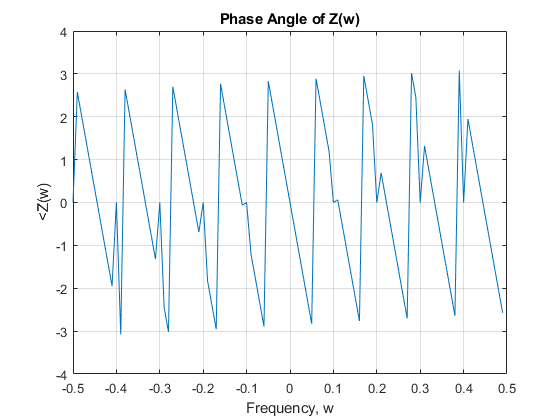

plot(f,fftshift(angle(Zw))); grid on;
title('Phase Angle of Z(w)'); xlabel('Frequency, w'); ylabel('<Z(w)');

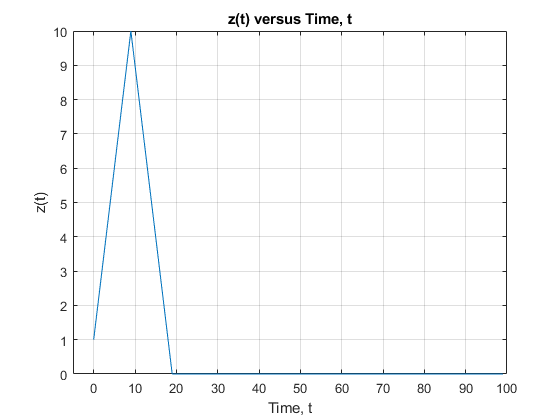


plot(t,zt); grid on; axis([-5 100 0 10]);
title('z(t) versus Time, t'); xlabel('Time, t'); ylabel('z(t)');

Result of z(t) using fft and ifft produced a result almost identical to A.1, aside from a slight shift.

This demonstrates the convolution theorem, that the convolution in the time domain can be found by the product in the frequency domain then the inverse Fourier Transform found.

 A.5: Modifying the PulseWidth to 5 and plotting the Magnitude and Phase Spectra of X(w)

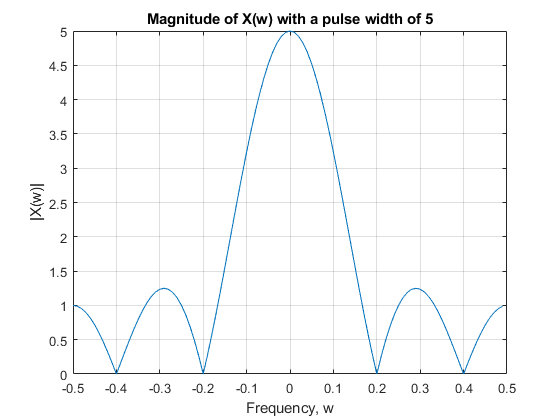

PulseWidth2 = 5;
x2 = [ones(1,PulseWidth2), zeros(1,N-PulseWidth2)];
Xf2 = fft(x2);

plot(f,fftshift(abs(Xf2))); grid on;
title('Magnitude of X(w) with a pulse width of 5'); 
xlabel('Frequency, w'); ylabel('|X(w)|');

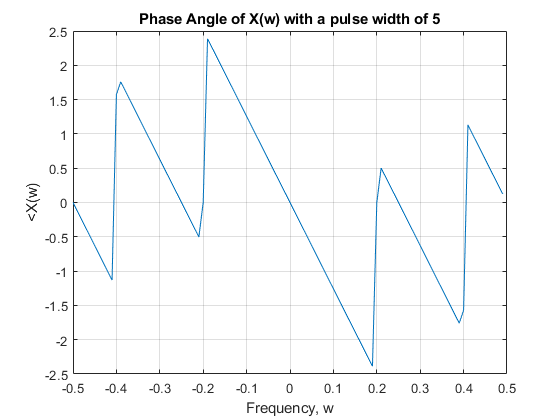


plot(f,fftshift(angle(Xf2))); grid on;
title('Phase Angle of X(w) with a pulse width of 5'); 
xlabel('Frequency, w'); ylabel('<X(w)');

 A.5: Modifying the PulseWidth to 25 and plotting the Magnitude and Phase Spectra of X(w)

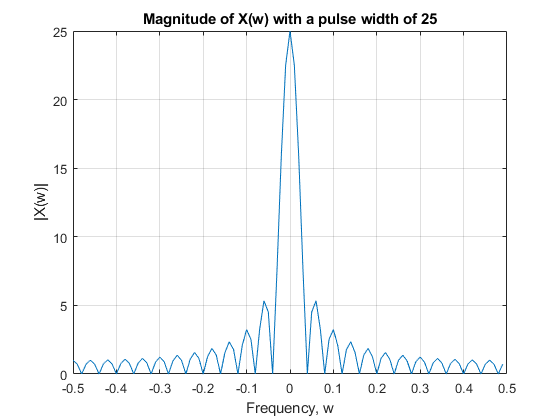

PulseWidth3 = 25;
x3 = [ones(1,PulseWidth3), zeros(1,N-PulseWidth3)];
Xf3 = fft(x3);

plot(f,fftshift(abs(Xf3))); grid on;
title('Magnitude of X(w) with a pulse width of 25'); 
xlabel('Frequency, w'); ylabel('|X(w)|');

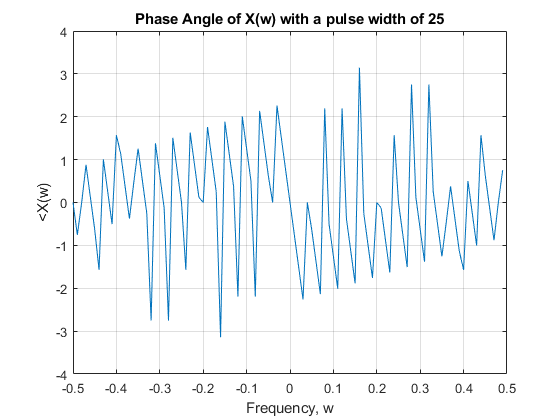


plot(f,fftshift(angle(Xf3))); grid on;
title('Phase Angle of X(w) with a pulse width of 25'); 
xlabel('Frequency, w'); ylabel('<X(w)');

As the pulse width increased, there were changes in frequency at more bandwidths

A.6: Calculating w+ and plotting both Magnitude and Phase spectra

wplus = x.*exp(1i*(pi/3)*t);
Wplus = fft(wplus)

Wplus =    0.0000 + 1.7321i   0.5775 + 1.9877i   1.1985 + 1.8885i   1.6461 + 1.4513i   1.7352 + 0.8165i   1.3780 + 0.2183i   0.6272 - 0.0792i  -0.3208 + 0.1388i  -1.1654 + 0.9641i  -1.5767 + 2.3201i  -1.2872 + 3.9615i  -0.1735 + 5.5209i   1.6931 + 6.5940i   4.0460 + 6.8414i   6.4740 + 6.0795i   8.5124 + 4.3373i   9.7519 + 1.8603i   9.9376 - 0.9394i   9.0309 - 3.5756i   7.2191 - 5.5997i   4.8698 - 6.7028i   2.4414 - 6.7812i   0.3744 - 5.9517i  -1.0082 - 4.5106i  -1.5678 - 2.8519i  -1.3660 - 1.3660i  -0.6304 - 0.3465i   0.3198 + 0.0715i   1.1646 - 0.0733i   1.6662 - 0.5999i   1.7226 - 1.2515i   1.3775 - 1.7758i   0.7902 - 1.9959i   0.1751 - 1.8527i  -0.2688 - 1.4092i  -0.4168 - 0.8180i  -0.2494 - 0.2656i   0.1509 + 0.0892i   0.6342 + 0.1628i   1.0362 - 0.0326i   1.2309 - 0.3999i   1.1688 - 0.7943i   0.8873 - 1.0725i   0.4929 - 1.1390i   0.1230 - 0.9740i  -0.1006 - 0.6355i  -0.1111 - 0.2362i   0.0848 + 0.0962i   0.4123 + 0.2617i   0.7561 + 0.2197i


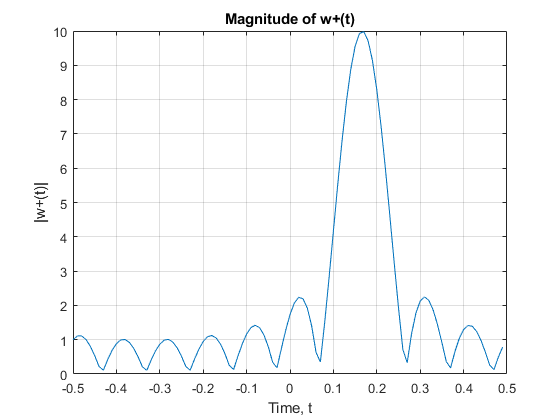

plot(f,fftshift(abs(Wplus))); grid on;
title('Magnitude of w+(t)'); xlabel('Time, t'); ylabel('|w+(t)|');

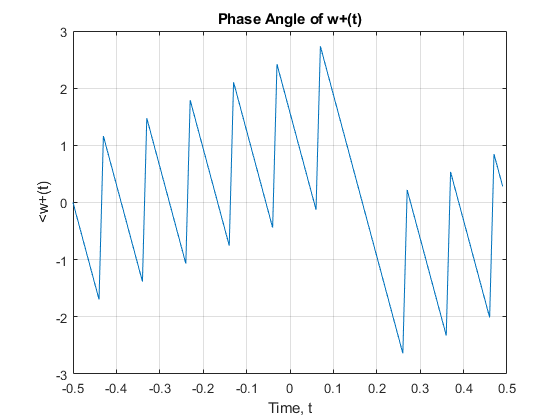

plot(f,fftshift(angle(Wplus))); grid on;
title('Phase Angle of w+(t)'); xlabel('Time, t'); ylabel('<w+(t)');

In A.3 the phase spectra graph yielded zero because there was no imaginary component of z(t), but in A.6 for w+ we have a non-zero portion of the phase spectra.

A.6 Calculating w_ and plotting both Magnitude and Phase spectra

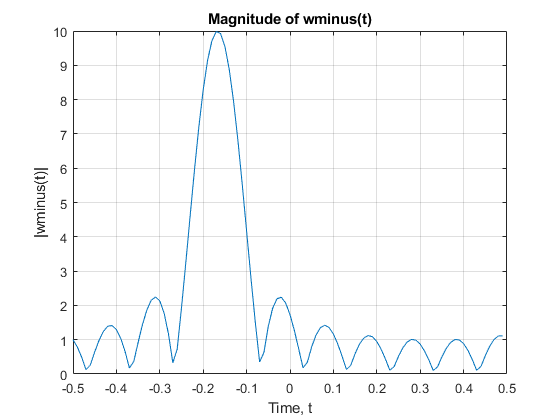

wminus = x.*exp(-1i*(pi/3)*t);
Wminus = fft(wminus);
plot(f,fftshift(abs(Wminus))); grid on;
title('Magnitude of wminus(t)'); xlabel('Time, t'); ylabel('|wminus(t)|');

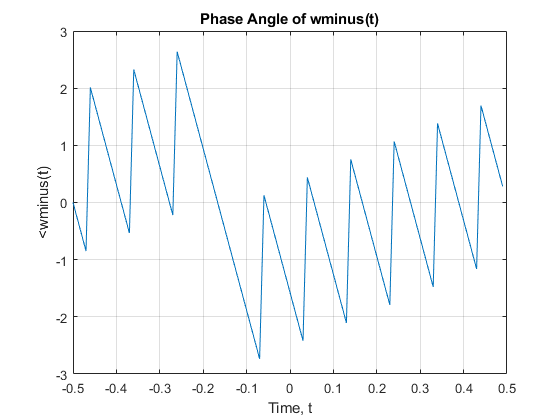

plot(f,fftshift(angle(Wminus))); grid on;
title('Phase Angle of wminus(t)'); xlabel('Time, t'); ylabel('<wminus(t)');

A.6 Calculating wc and plotting both Magnitude and Phase spectra

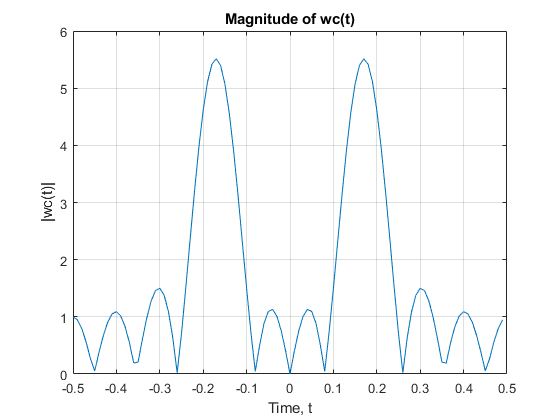

wc = x.*cos(t*pi/3);
Wc = fft(wc);
plot(f,fftshift(abs(Wc))); grid on;
title('Magnitude of wc(t)'); xlabel('Time, t'); ylabel('|wc(t)|');

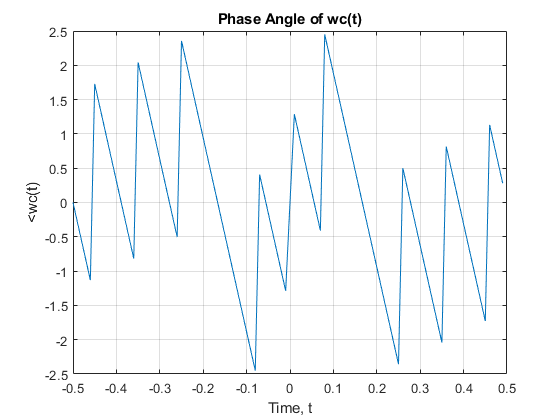

plot(f,fftshift(angle(Wc))); grid on;
title('Phase Angle of wc(t)'); xlabel('Time, t'); ylabel('<wc(t)');

B.1

load("Lab4_Data.mat");

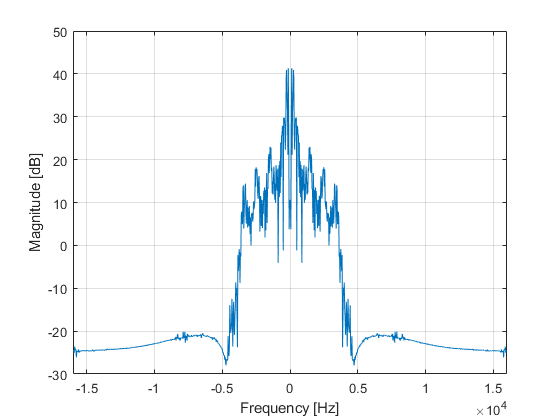

MagSpect(xspeech)

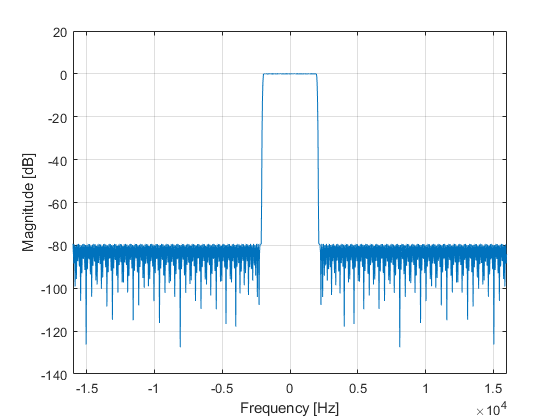

MagSpect(hLPF2000)

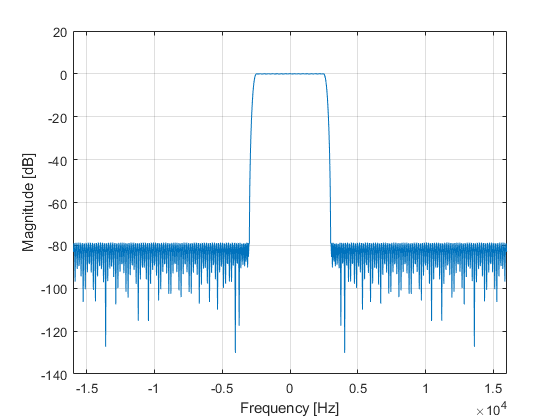

MagSpect(hLPF2500)

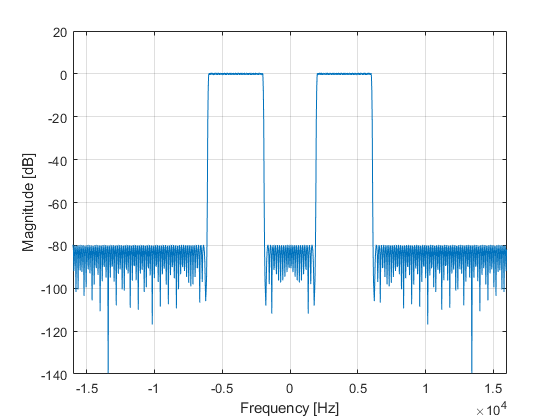

MagSpect(hChannel)

Coder

Step 1:

LPF1 = fft(hLPF2000, 80000);
xsp1 = fft(transpose(xspeech), 80000);
xsp2 = LPF1.*xsp1;
xsp3 = ifft(xsp2);

Step 2:

xsp4 = xsp3.*transpose(osc(4000, 80000));

Step 3:

Ch1 = fft(hChannel, 80000);
xsp5 = fft(xsp4, 80000);
xsp6 = xsp5.*Ch1;
xsp7 = ifft(xsp6);


Decoder

Step 4:

xsp8 = xsp7.*transpose(osc(4000, 80000));

Step 5:

xsp9 = fft(xsp8, 80000);

Step 6:

xsp10 = LPF1.*xsp9;
xsp11 = ifft(xsp10);

sound(xsp11,32000)

sound(xspeech,32000)

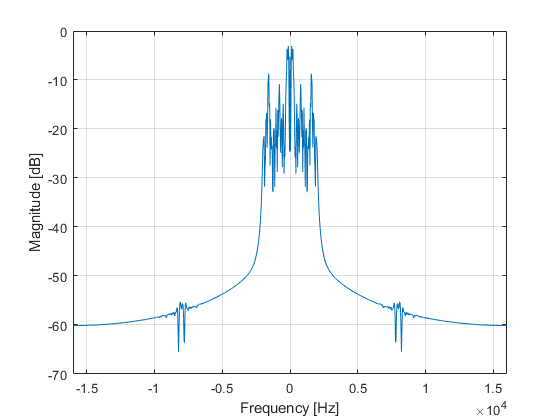

MagSpect(xsp11)

Coder

Step 1:

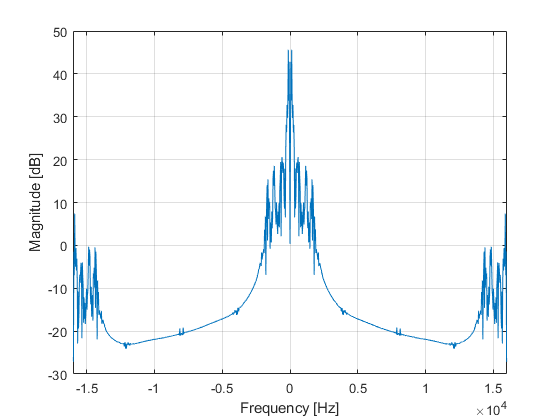

xspeech2 = zeros(1,160000);
for i = 1:1:80000
    xspeech2(2*i - 1) = xspeech(i);
    xspeech2(2*i) = xspeech(i);
end
MagSpect(xspeech2)

Step 2:

qLPF1 = fft(hLPF2000, 160000);
qxsp1 = fft(xspeech2, 160000);
qxsp2 = qLPF1.*qxsp1;
qxsp3 = ifft(qxsp2);

Step 3:

qxsp4 = qxsp3.*transpose(osc(4000, 160000));

Step 4:

qCh1 = fft(hChannel, 160000);
qxsp5 = fft(qxsp4, 160000);
qxsp6 = qxsp5.*qCh1;
qxsp7 = ifft(qxsp6);


Decoder

Step 5:

qxsp8 = qxsp7.*transpose(osc(4000, 160000));

Step 6:

qxsp9 = fft(qxsp8, 160000);

Step 7:

qxsp10 = qLPF1.*qxsp9;
qxsp11 = ifft(qxsp10);

Step 8:

qxsp12 = zeros(1,80000);
for i = 1:1:80000
    qxsp12(i) = qxsp11(i*2);
end

MagSpect of the final signal

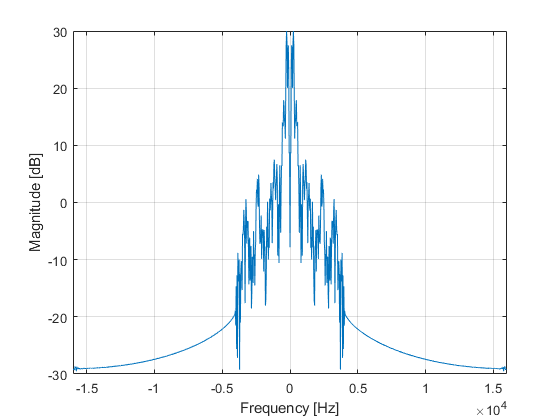

MagSpect(qxsp12)

Audio of the final signal

sound(qxsp12,32000)

Audio of the original signal

sound(xspeech, 32000)

sound(xspeech2,32000)